# **Training CN-vs-MCIc**

Due to memory (RAM) limits instead of loading the whole Dataset, we are going to process just few images (5, in our case) per time during each fold.

**With the 20-Fold Cross validation we will:**

**    - Find patterns to use for Testing (index==fold) and Training (index!=fold)**

**    - Train AlexNet (until all of the Training images are processed), in particular we will:**

- **Load 5 random RMI training images (single image dimension: 121x145x121)**

- **Transform them into five hundred (5*100) 227x227x3 images (~500MB)**

- **Perform Data Augmentation techniques**

- **Complete the training phase.**

**    - Save the network trained in this way**

**    - Proceed with Validation (until all the Testing images are processed), we will:**

- **Load the 5 RMI Testing images (single image dimension: 121x145x121)**

- **Transform them into five hundred (5*100) 227x227x3 images (~500MB)**

- **Perform Data Augmentation techniques again**

- **Use trained network to perform classification**

- **Add results to a prediction array**

**    - Compute Accurancy**

## **1) Defining the Network**

by modifing the last 3 layers of AlexNet

clear all
warning off

siz=[227 227]; % input size of the CNN (AlexNet)

net = alexnet;
layers=net.Layers; % saving layers
layers(end-2)=fullyConnectedLayer(2,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20);
layers(end-1)=softmaxLayer;
layers(end)=classificationLayer;

## **2) Setting parameters for neural network**

miniBatchSize = 30;
learningRate = 1e-4;
optimizer='sgdm';
options=trainingOptions(optimizer,...
    "MiniBatchSize",miniBatchSize,...
    "InitialLearnRate",learningRate,...
    'MaxEpochs',30,...
    "Verbose",false,...
    "Plots","training-progress");

## **3) Loading the Dataset**

**Loading CN.mat and MCIc.mat**

**Concatenating CN_training, CN_testing, MCIc_training, MCIc_testing in a single cell array**

% Concatenate all dataset files in a single cell array (a cell array is a
% data type with indexed data containers called cells, where each cell can
% contain any type of data)
load CN.mat
load MCIc.mat
dataset=cat(1,CN_training,CN_testing,MCIc_training,MCIc_testing);

% Create label array
lengthClass1=(length(CN_training)+length(CN_testing));
lengthClass2=(length(MCIc_training)+length(MCIc_testing));
label(1:lengthClass1)=1; %Cognitive Normal = 1
label(lengthClass1:lengthClass1+lengthClass2)=2;

clear CN_training CN_testing MCIc_training MCIc_testing lengthClass1 lengthClass2

**In this section we find patterns we will use for Testing (Indices==fold) and Training (Indices!=fold)**

% Splitting the dataset in Training and Testing for this fold
fold=1;

load indices_CN-vs-MCIc.mat

trainingData=dataset(Indices~=fold);
trainingLabel=label(Indices~=fold);

testData=dataset(Indices==fold);
testLabel=label(Indices==fold);

clear dataset label

**Shuffling the dataset**

Instead of directly shuffling trainingData, to save computation we create and shuffle a indicesVector

indicesVector=[1:length(trainingData)]; % Containg indices from 1 to trainingData length (~228)
indicesVector=indicesVector(randperm(length(indicesVector))); % Shuffle vector of indices


## **4) Training**

**This section of code will be repeatedly executed until all the Training images are processed.**

### **4.1) Loading 5 RMI training images**

setSize=5;
trainingImages=[];
label=[]; % labels of classes 
labelID=[]; % labels of ID
tmpTR=1;
for mri=1:setSize
    
    % Extract single MRI
    IMG=trainingData{indicesVector(mri)};
    
    % Transform MRI picture into 100 images 227x227x3
    IMG=mriToCNN(IMG,siz);
    trainingImages(:,:,:,tmpTR:tmpTR+size(IMG,4)-1)=IMG;
    
    % -------------------???NON CAPISCO: Return label vector the labels of the new 100 pictures
    class=trainingLabel(indicesVector(mri));
    label(tmpTR:tmpTR+size(IMG,4)-1)=class;
    
    % Saving single person's ID
    labelID(tmpTR:tmpTR+size(IMG,4)-1)=indicesVector(mri);
    
    tmpTR=tmpTR+size(IMG,4); %Increasing counter by 100
    
    clear IMG;
end

% The label is a series of one hundred "1" and one hundred "2", so we
% decided to shuffle again to obtain:
indicesVector=[1:length(label)];
indicesVector=indicesVector(randperm(length(indicesVector))); % Shuffling vector of indices
label=label(indicesVector);
labelID=labelID(indicesVector);
trainingImages=trainingImages(:,:,:,indicesVector);
size(trainingImages)

ans =    227   227     3   500


### **4.2) Performing Data augmentation techniques on the TrainSet**

%imageAugmenter = imageDataAugmenter( ...
        %'RandXReflection',true, ...
        %'RandXScale',[1 2], ...
        %'RandYReflection',true, ...
        %'RandYScale',[1 2],...
        %'RandRotation',[-10 10],...
        %'RandXTranslation',[0 5],...
        %'RandYTranslation', [0 5]);
    %trainingImages = augmentedImageSource(imageSize,trainingImages,categorical(y'),'DataAugmentation',imageAugmenter);

### **4.3) Training**

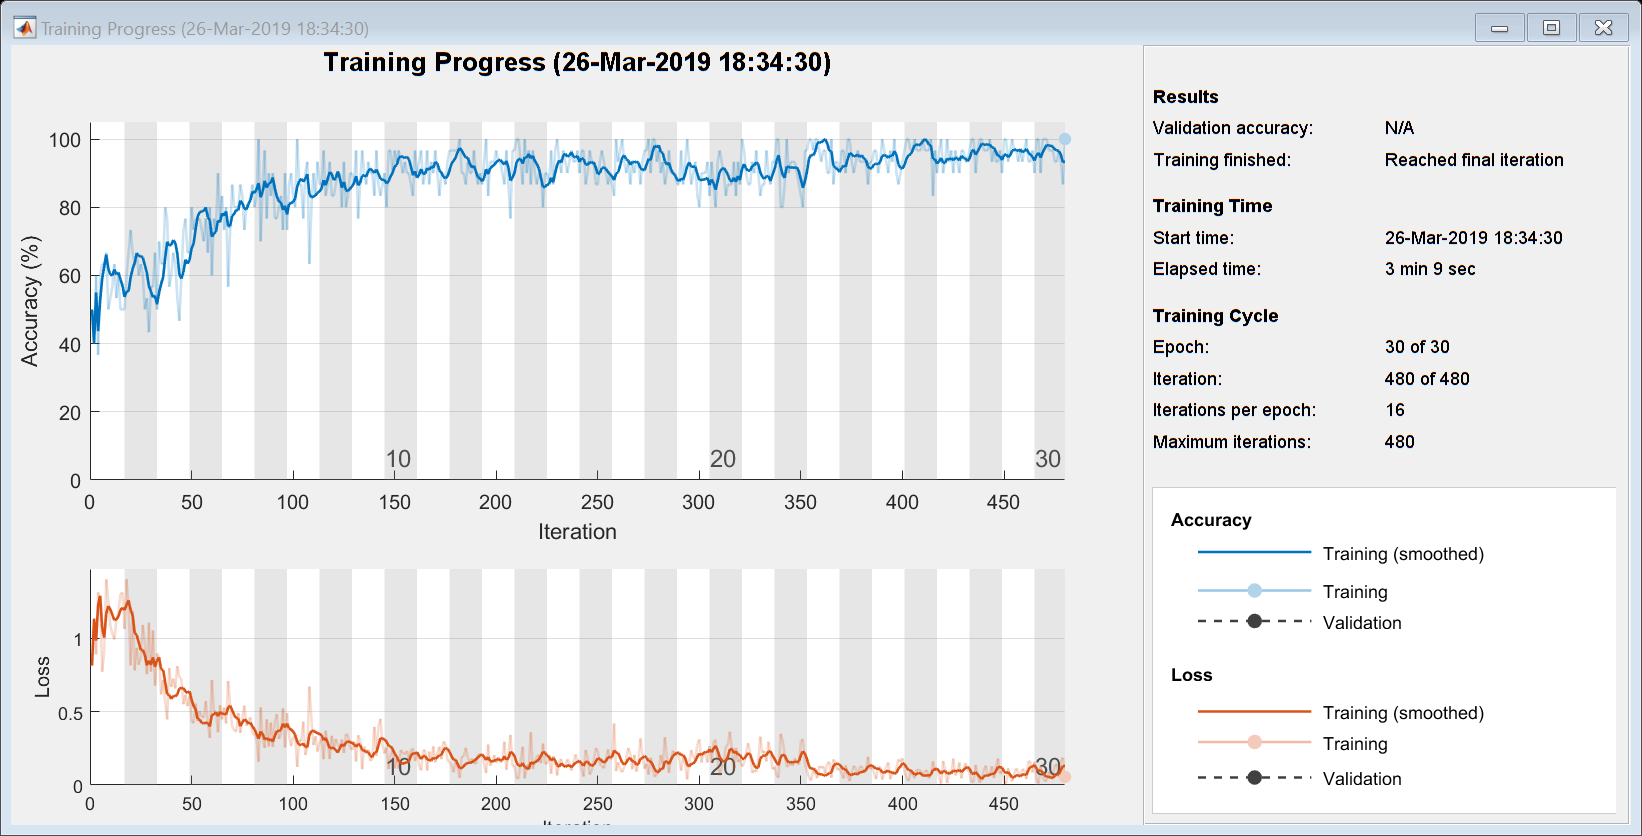

Y=categorical(label');

[trainedNet,info]=trainNetwork(trainingImages,Y,layers,options);

info

info = struct with fields:
        TrainingLoss: [1×480 double]
    TrainingAccuracy: [1×480 double]
       BaseLearnRate: [1×480 double]


### **4.4) Saving trained network**

## **5) Validation**

### **5.1) Loading TestSet**

totPredictions=[];
totLabels=[];
totLabelsID=[]


totLabelsID =

     []




count=1; % image to test
for i=1:length(testData)
    label=[];   % labels of classes 
    labelID=[]; % labels of ID
    validationImages=[];
    tmpTR=1;
    for mri=1:setSize
        
        % Extract single MRI
        IMG=testData{count};
        
        % Transform MRI picture into one hundred 227x227x3 images
        IMG=mriToCNN(IMG,siz);
        validationImages(:,:,:,tmpTR:tmpTR+size(IMG,4)-1)=IMG;
        
        % --------------------???NON CAPISCO: Return label vector the labels of the new 100 pictures
        class=testLabel(count);
        label(tmpTR:tmpTR+size(IMG,4)-1)=class;
        
        % Saving single person's ID
        labelID(tmpTR:tmpTR+size(IMG,4)-1)=count;
        
        tmpTR=tmpTR+size(IMG,4); %%Increasing counter by 100
        
        clear IMG;
        
        count=count+1;
        if count>length(testData)
            break;
        end   
    end

### **5.2) Data Augmentation on TestSet**

%imageAugmenter = imageDataAugmenter( esempio: 'RandRotation', [-180 180])
%esempio, inserire prima di validationImages la dimensione: imageSize = [28 28 1];
%validationImages = augmentedImageSource((imageSize,XTrain,YTrain,'DataAugmentation',imageAugmenter)

### **5.3) Validatation**

    predictions = classify(trainedNet,validationImages);

    totPredictions=cat(1,totPredictions,predictions);
    totLabels=cat(2,totLabels,label);
    totLabelsID=cat(2,totLabelsID,labelID);
    
    clear validationImages predictions label
    
    if count>length(testData)

TP = 244

        break;

TN = 231

    end

FP = 569

end

FN = 56

predictions=totPredictions;
label=totLabels;

precision = 0.3001

labelID=totLabelsID;

recall = 0.8133

f1 = 0.4385

## **6) Metrics**

predictions=double(predictions);

specificity = 0.7113

accuracy = 0.4318

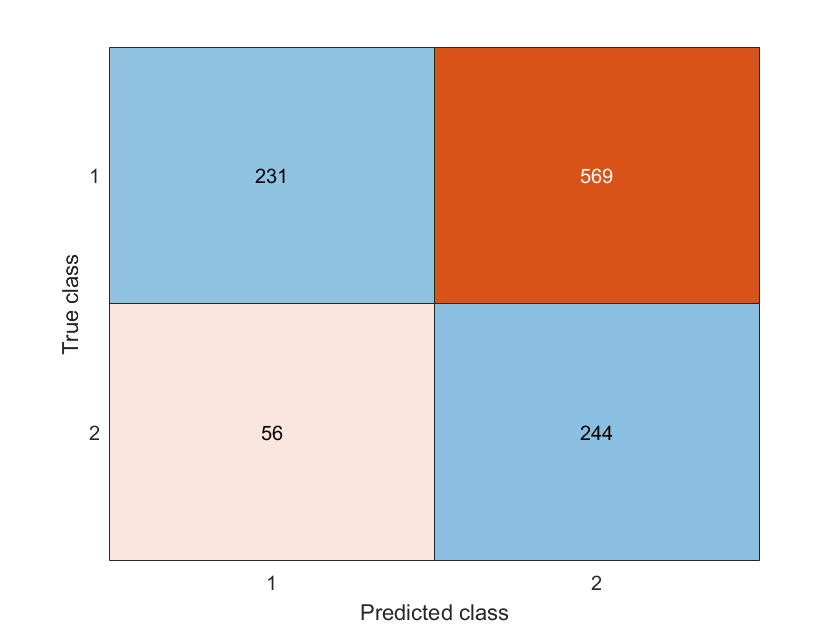

ans =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 double]

  Show all properties


TP= sum(and((predictions==2)',label==2))
TN= sum(and((predictions==1)',label==1))
FP= sum(and((predictions==2)',label==1))
FN= sum(and((predictions==1)',label==2))


precision= TP/(TP+FP)
recall=TP/(TP+FN)
f1=2*(precision*recall)/(precision+recall)
specificity=FP/(FP+TN)
accuracy=(TP+TN)/(TP+TN+FP+FN)

%accuracy = sum(predictions' == label)/numel(label)

confusionchart(label,predictions)

## **7) Save the trained model**

%<---DA MODIFICARE save('filename','VariableName(trained nnet object)')

**Function that transforms a MRI picture into 100 227x227x3 images (~100MB)**

function [IMG]=mriToCNN(IMG,siz) 
    % Removing NaN values
    IMG(find(isnan(IMG)))=0;
    
    % Creating one hundred 227x227x3 pictures
    % Resizing each 121x145 slice to 227x227
    % Excluding the first and the last 10 layers because are almost completely made up fo zeroes
    clear RID
    for livello=11:110
        RID(:,:,1,livello-10)=imresize(IMG(:,:,livello),[siz(1) siz(2)]);
        RID(:,:,2,livello-10)=imresize(IMG(:,:,livello),[siz(1) siz(2)]);
        RID(:,:,3,livello-10)=imresize(IMG(:,:,livello),[siz(1) siz(2)]);
    end
    
    clear IMG
    
    % Normalizing values <--------------------------------- TODO: find a better normalization
    M=max(RID(:));
    IMG=floor(RID.*(255/M));
end